## Redundancy in cartesian Dynamic Task

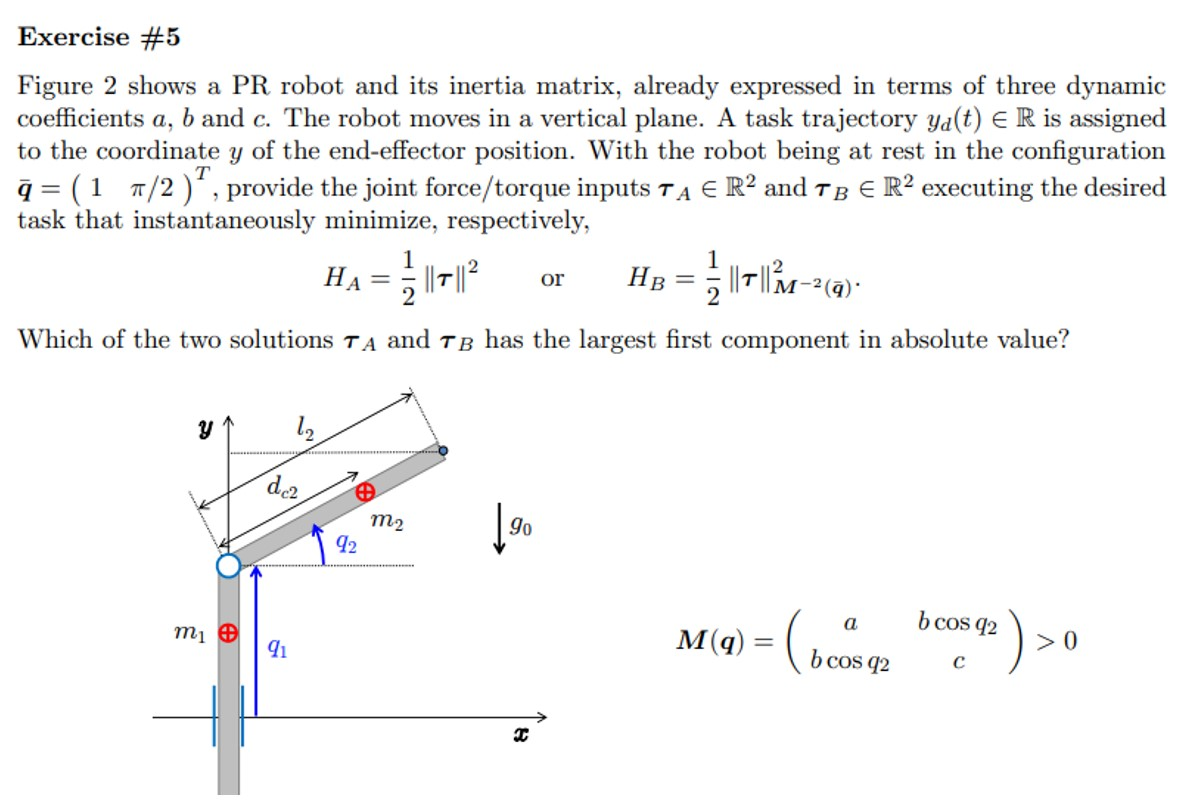

syms q1 q2 dq1 dq2 a b c positive
syms l1 l2 m1 m2 d1 d2  g0 positive

% Given from exercise
M = [a b*cos(q2);
     b*cos(q2) c;];

% Jacobian
p = [l2*cos(q2);
    q1+l2*sin(q2);];

J = jacobian(p,[q1,q2]);

disp("Jacobian: ")

Jacobian: 


disp(J)

$$\left(\begin{array}{cc} 0 & -l_{2}\,\sin\left(q_{2}\right)\\ 1 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


% Velocity and Acceleration
r_dot = [diff(p(1), q1)*dq1+diff(p(1), q2)*dq2;
        diff(p(2), q1)*dq1+diff(p(2), q2)*dq2;];
r_dot_dot = [diff(r_dot(1), q1)*dq1+diff(r_dot(1), q2)*dq2;
             diff(r_dot(2), q1)*dq1+diff(r_dot(2), q2)*dq2;];
disp("r_dot: ");

r_dot: 


disp(r_dot);

$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

disp("r_dot_dot: ");

r_dot_dot: 


disp(r_dot_dot);

$$\left(\begin{array}{c} -{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\cos\left(q_{2}\right)\\ -{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$


% J dot
J_dot = [diff(J(1,1), q1)*dq1+diff(J(1,1), q2)*dq2 diff(J(1,2), q1)*dq1+diff(J(1,2), q2)*dq2;
         diff(J(2,1), q1)*dq1+diff(J(2,1), q2)*dq2 diff(J(2,2), q1)*dq1+diff(J(2,2), q2)*dq2;]

$$J\_dot = \left(\begin{array}{cc} 0 & -{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)\\ 0 & -{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$


% Gravity terms
U1 = m1*g0*q1;
U2 = m2*g0*(q1+d2*sin(q2));

U = [U1+U2;];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100);

disp('Potential Energy: ');

Potential Energy: 


disp(U);

$$g_{0}\,m_{1}\,q_{1}+g_{0}\,m_{2}\,\left(q_{1}+d_{2}\,\sin\left(q_{2}\right)\right)$$

disp('Gravity terms g(q): ');

Gravity terms g(q): 


disp(g_q);

$$\left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


% CORIOLIS/CENTRIFUGAL VECTOR c(q,dq)
% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -b\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -b\,{{\mathrm{dq}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


% tau a
val_q1 = 1;
val_q2 = pi/2;
p_eval       = subs(p, [q1, q2], [val_q1, val_q2]);
r_dot_eval   = subs(r_dot, [q1, q2], [val_q1, val_q2])

$$r\_dot\_eval = \left(\begin{array}{c} -{\mathrm{dq}}_{2}\,l_{2}\\ {\mathrm{dq}}_{1} \end{array}\right)$$

r_dot_dot_eval = subs(r_dot_dot, [q1, q2], [val_q1, val_q2])

$$r\_dot\_dot\_eval = \left(\begin{array}{c} 0\\ -{{\mathrm{dq}}_{2}}^{2}\,l_{2} \end{array}\right)$$

J_eval       = subs(J, [q1, q2], [val_q1, val_q2])

$$J\_eval = \left(\begin{array}{cc} 0 & -l_{2}\\ 1 & 0 \end{array}\right)$$

J_dot_eval   = subs(J_dot, [q1, q2], [val_q1, val_q2])

$$J\_dot\_eval = \left(\begin{array}{cc} 0 & 0\\ 0 & -{\mathrm{dq}}_{2}\,l_{2} \end{array}\right)$$

M_eval       = subs(M, [q1, q2], [val_q1, val_q2])

$$M\_eval = \left(\begin{array}{cc} a & 0\\ 0 & c \end{array}\right)$$

g_q_eval     = subs(g_q, [q1, q2], [val_q1, val_q2])

$$g\_q\_eval = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ 0 \end{array}\right)$$

c_vec_eval       = subs(c_vec, [q1,q2], [val_q1, val_q2])

$$c\_vec\_eval = \left(\begin{array}{c} -b\,{{\mathrm{dq}}_{2}}^{2}\\ 0 \end{array}\right)$$


tau_a = pinv(J_eval*inv(M_eval))*(r_dot_dot_eval -J_dot_eval*[dq1; dq2;]+J_eval*inv(M_eval)*(g_q_eval+c_vec_eval))

$$tau\_a = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)-b\,{{\mathrm{dq}}_{2}}^{2}\\ 0 \end{array}\right)$$


% tau_b
tau_b = (M_eval*pinv(J_eval))*(r_dot_dot_eval -J_dot_eval*[dq1; dq2;]+J_eval*inv(M_eval)*(g_q_eval+c_vec_eval))

$$tau\_b = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)-b\,{{\mathrm{dq}}_{2}}^{2}\\ 0 \end{array}\right)$$